Ejemplo de diseño de filtro digital

autor: Filipuzzi, Fernando Rafael

versión: 20230314

Matlab:2022b

function [B,A]=mi_fir2(varargin)

% N, W, VENTANA
% number of arguments check
narginchk(2,4);
N=double(varargin{1});
Wn=double(varargin{2});
TIPO="paso bajo"; 
if nargin>=3
    TIPO=varargin{3};
end
VENTANA="rectangular";
if nargin>=4
    VENTANA=varargin{4};
end

            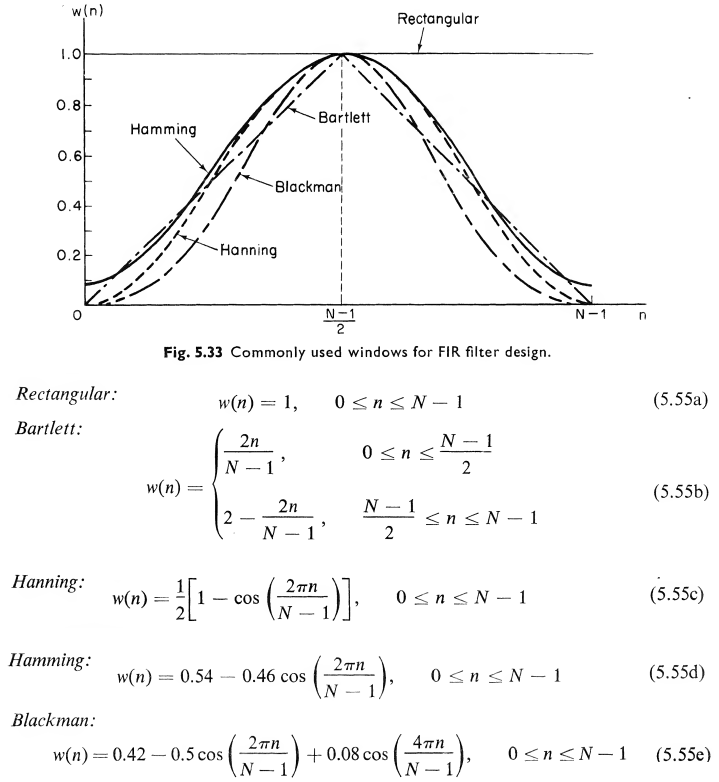

    %
    a= (N)/2;    
    if mod(N,2)==0
        a= (N-1)/2;
    end

    %selección de la ventana
    w = @(m) 1;
    switch VENTANA
        case "rectangular"
            w = @(m) 1;
        case "hanning"
            w = @(m) 1/2*[1-cos(2*pi*m/(N-1))];
        case "hamming"
            w = @(m) 0.54 - 0.46*cos(2*pi*m/(N-1));
        case "blackman"
            w = @(m) 0.42 - 0.5*cos(2*pi*m/(N-1))- 0.08*cos(4*pi*m/(N-1));            
    end

[dietrich]       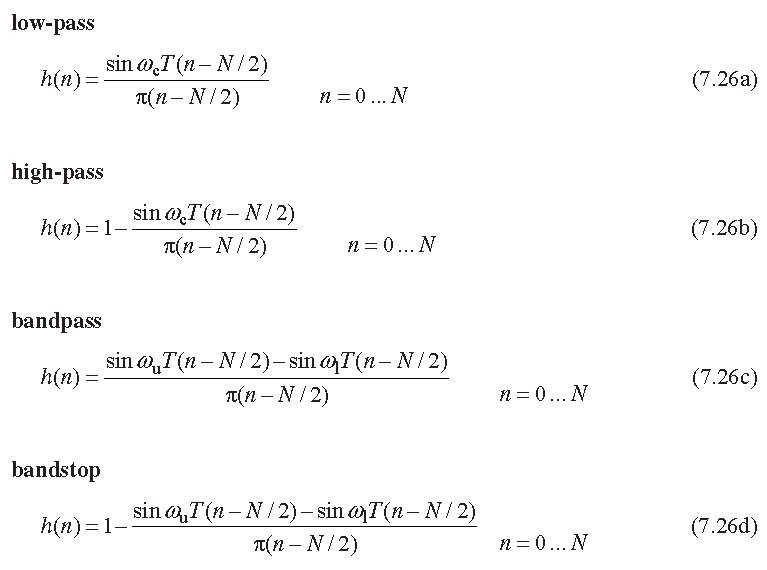

    %
    switch TIPO
        case "pasa_bajo"
            Wn=Wn(end);
            hn = @(m) (m~=a).*(sin(pi*Wn*(m-a) )./( pi*(m-a) ))+(m==a).*Wn; 
        case "pasa_alto"
            Wn=Wn(end);
            hn = @(m) 1-sin(pi*Wn*(m-a))./( pi*(m-a) );
        case "pasa_banda"
            W1=Wn(1);
            W2=Wn(2);
            hn = @(m) sin(pi*W1*(m-a) )./( pi*(m-a) ) - sin(pi*W2*(m-a) )./( pi*(m-a) );              
        case "rechaza_banda"
            W1=Wn(1);
            W2=Wn(2);
            hn = @(m) 1- sin(pi*W1*(m-a) )./( pi*(m-a) ) - sin(pi*W2*(m-a) )./( pi*(m-a) );    
    end

    %
    h = hn(0:N-1);

    %
    A=1;
    B=h.*w(0:N-1);

    if TIPO=="pasa_bajo"
        %B=B/max(20*log(B(:)))*Wn(end);
       % [k,p]=max(log(B(:)));
        B=B/Wn(end)*max(B);
    end

    if TIPO=="pasa_alto"
      %  B=B;
    end

    if TIPO=="pasa_banda"
       B=B*(sqrt(Wn(end)*Wn(1))/2)/max(B);
    end
end